# Principle Component Analysis of Hiring Data

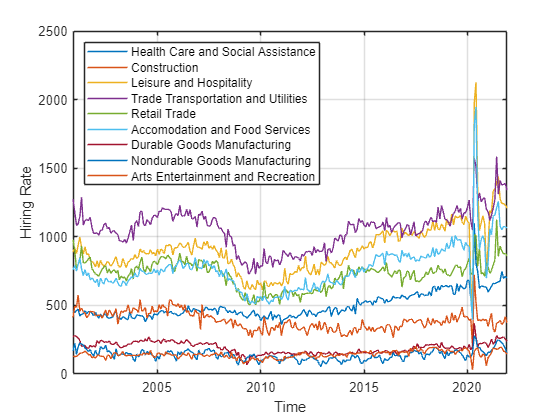

load ./data/hiringData.mat

plot(time, X)
grid on
legend(categories, "Location", "northwest")
ylabel("Hiring Rate")
xlabel("Time")

## Task 1

The columns of the matrix X contain the number of new hires across nine employment sectors (Health Care, Construction, Retail, etc.) measured in the thousands and spanning from 12/2000 to 12/2021.

The first step in any principal component analysis is to center the data so that each column has a mean of zero.

You can center the columns of a matrix using the `normalize` function:

`a` `=` `normalize``(``b``,``"center"``)`

X = normalize(X, "center")

X = 1.0e+03 *

   -0.0382    0.0241   -0.0177    0.2180    0.2523   -0.0065    0.0795    0.0305   -0.0123
   -0.0512    0.1051    0.0113    0.1230    0.1713    0.0265    0.0895    0.0855   -0.0153
   -0.0312    0.0961   -0.0297    0.0250    0.0293   -0.0155    0.0805    0.0035   -0.0143
   -0.0232    0.1851    0.0273    0.0350    0.0733    0.0345    0.0705    0.0585   -0.0073
   -0.0752    0.0681    0.0903    0.0900    0.0983    0.0815    0.0525    0.0875    0.0087
   -0.0602    0.0901    0.0133    0.2300    0.2043    0.0015    0.0095    0.0805    0.0107
   -0.0592    0.0611   -0.0347    0.0280    0.0833   -0.0495    0.0145    0.0705    0.0157
   -0.0352    0.0541    0.0203    0.0600    0.0793   -0.0035    0.0165    0.0515    0.0237
   -0.0582    0.0201   -0.0377    0.0690    0.0943   -0.0515    0.0005    0.0415    0.0137
   -0.0422    0.0371   -0.0317    0.0590    0.1103   -0.0275   -0.0055    0.0245   -0.0043


## Task 2

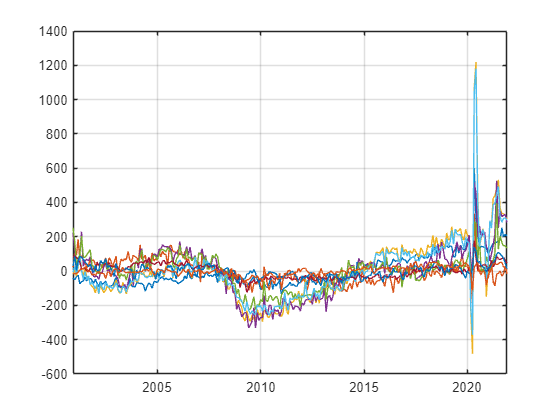

plot(time, X)
grid on

## Task 3

[U,S,V] = svd(X, "econ");

## Task 4

The columns of the matrix X contain the number of new hires across nine employment sectors (Health Care, Construction, Retail, etc.) measured in the thousands and spanning from 12/2000 to 12/2021.

The first step in any principal component analysis is to center the data so that each column has a mean of zero.

You can center the columns of a matrix using the `normalize` function:

`a` `=` `normalize``(``b``,``"center"``)`

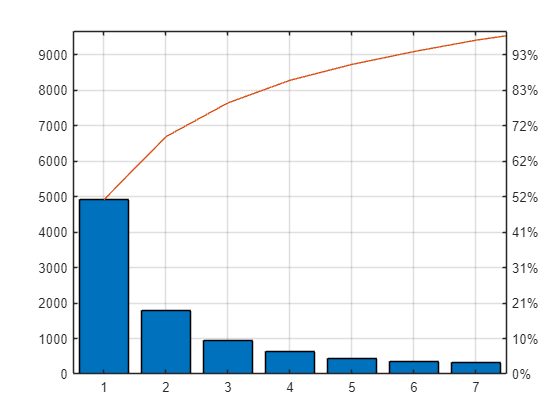

pareto(diag(S))
grid on

## Task 5

The columns of the left singular matrix represent the principal components of the matrix `X`. Based on the pareto chart, the first two singular values describe roughly 70% of the original data. Therefore, the first two principal components should reproduce the broad overall shape of the hiring rates over time across all sectors.

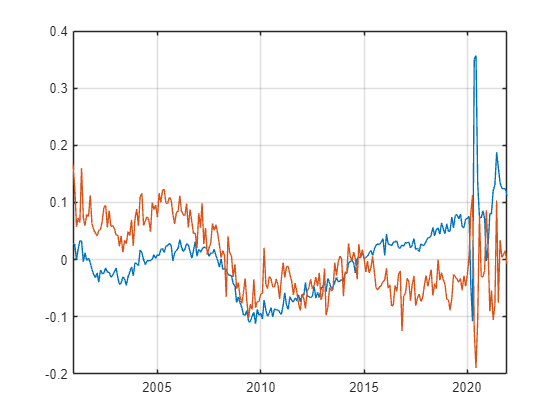

plot(time, U(:, 1:2))
grid on

## Task 6

The columns of the original matrix can be approximated with linear combinations of the principle components. The coefficients of the linear combinations are the columns of the matrix `S*V'`.

coeffs = S*V';